I = imread("Daniel_Bra_Bild.JPG")

I = 4096×3072×3 uint8 array
I(:,:,1) =

  Columns 1 through 1 666

   185   185   185   185   185   185   185   185   185   185   185   185   185   185   185   185   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   189   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   193   193   193   193   193   193   193   193   193   193   193   

I_r = zeros(size(I,1),size(I,2),size(I,3));
I_r(:,:,1) = I(:,:,1);
I_g = zeros(size(I,1),size(I,2),size(I,3));
I_g(:,:,2) = I(:,:,2);
I_b = zeros(size(I,1),size(I,2),size(I,3));
I_b(:,:,3) = I(:,:,3);


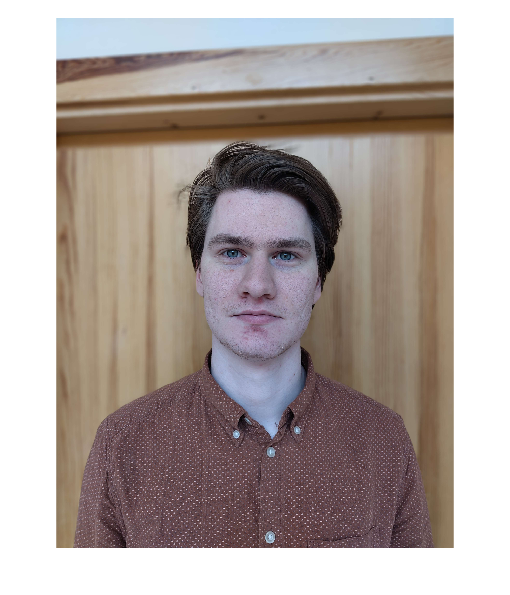


imshow(I)

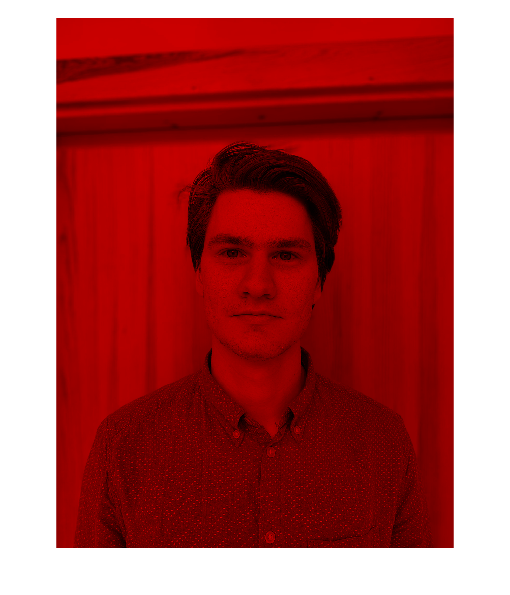

imshow(I_r/255)%Red

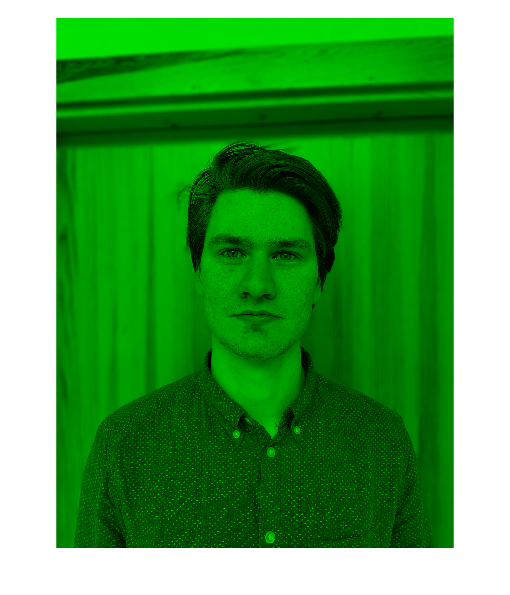

imshow(I_g/255)%Gree

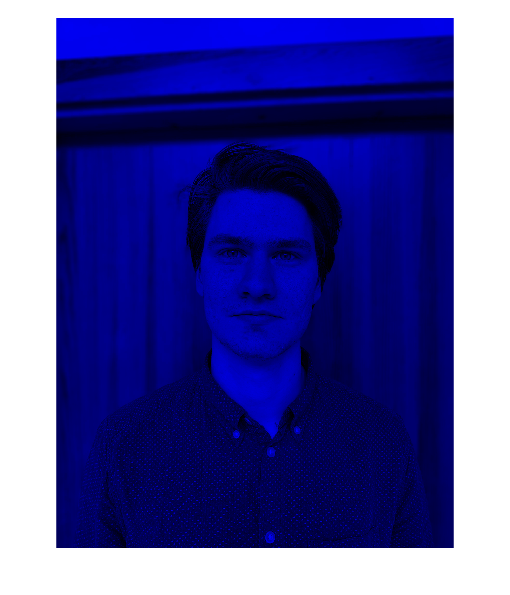

imshow(I_b/255)%Blue

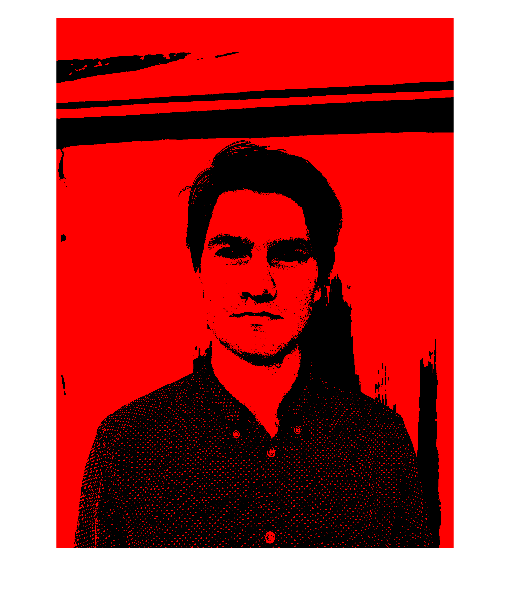

threshold = 0.5 ;
I_r_thres = 1.*(I_r/255>threshold);
imshow((I_r_thres))%Red

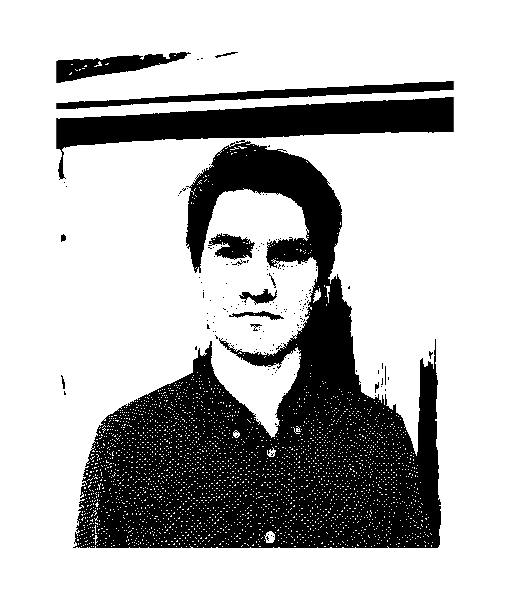

imshow((I_r_thres(:,:,1)))%Red(B/W)

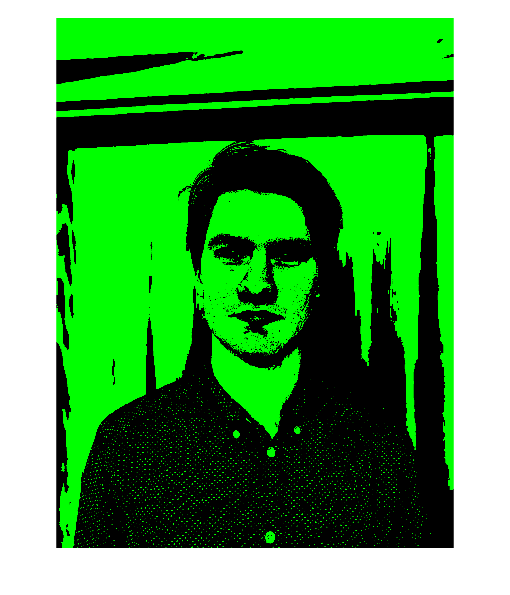

I_g_thres = 1.*(I_g/255>threshold);
imshow((I_g_thres))%Green

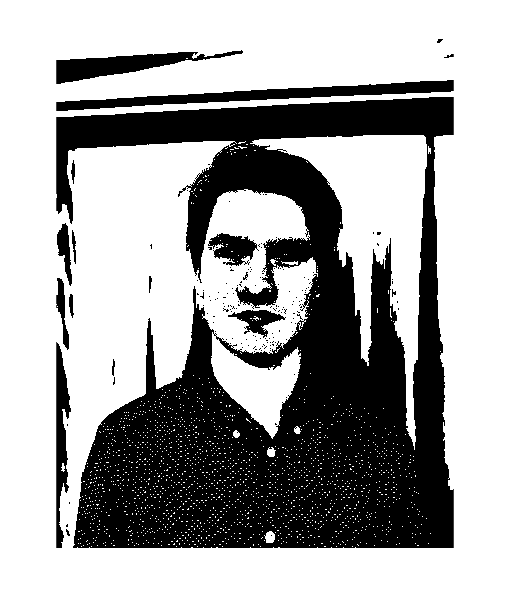

imshow((I_g_thres(:,:,2)))%Green(B/W)

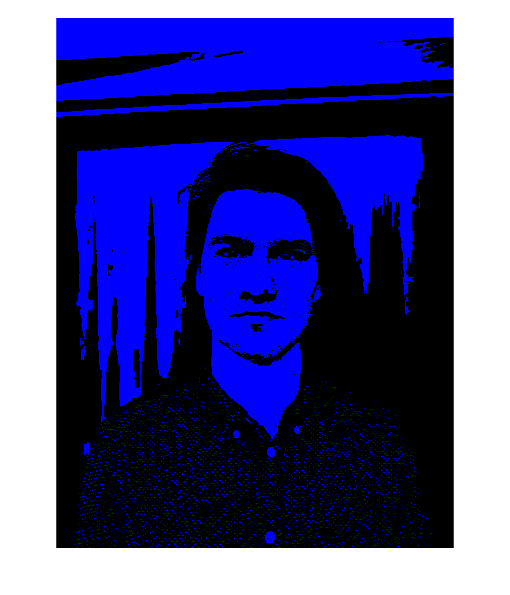

I_b_thres = 1.*(I_b/255>threshold);
imshow((I_b_thres))%Blue

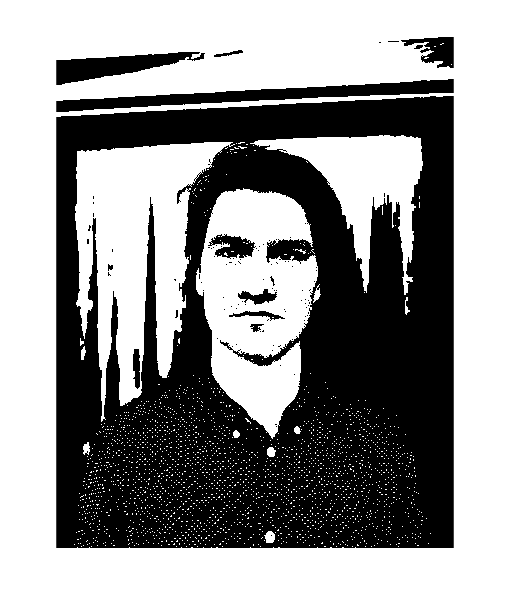

imshow((I_b_thres(:,:,3)))%Blue(B/W)

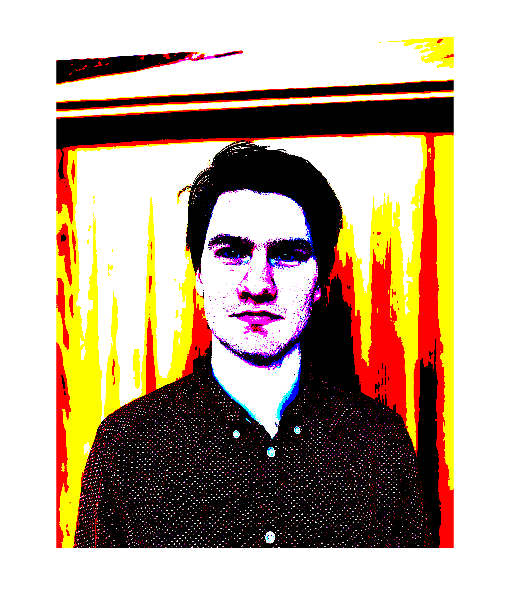

imshow(I_r_thres + I_b_thres + I_g_thres)

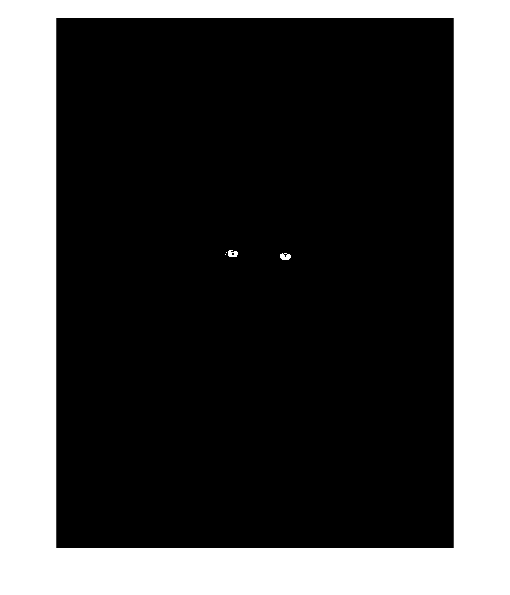

maskedImage = load("BW_HSV.mat").BW_HSV;
figure
title("Mask of HSV")
imshow(maskedImage) %Gained from the color thresholder app

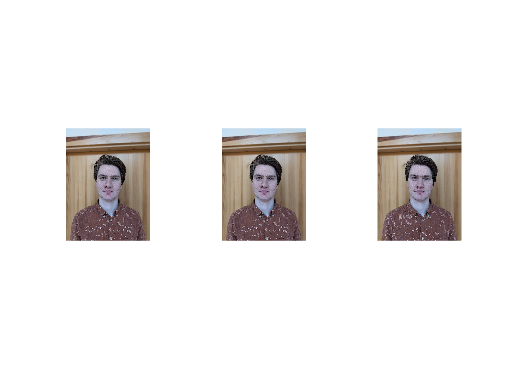

I_n = I;

I_n = I_n.*cast(maskedImage,"uint8");

I_p = I - I_n;


figure
title("Different shifts in color")
tiledlayout(1,3)

for shift = 1:3
    I_c = I_p;
    for i = 1:3
        I_c(:,:,mod(i,3)+1) = I_c(:,:,mod(i,3) + 1) + I_n(:,:,mod(i + shift,3)+1);
    end
    nexttile
    imshow(I_c)
end

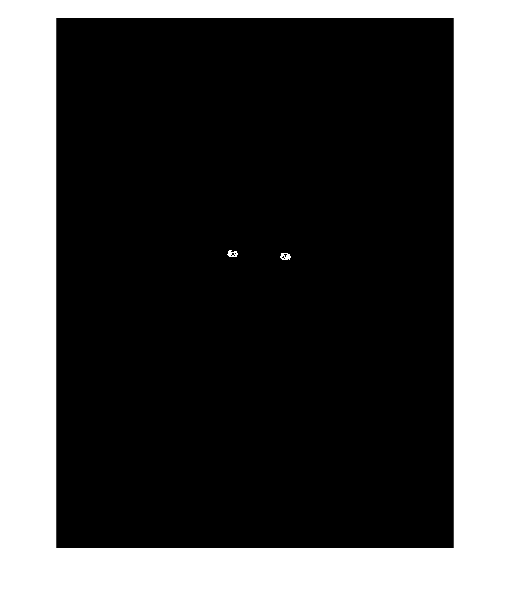

maskedImage = load("BW_YbCbCr.mat").BW_YCbCr;
figure
title("Mask of YbCbCr")
imshow(maskedImage) %Gained from the color thresholder app

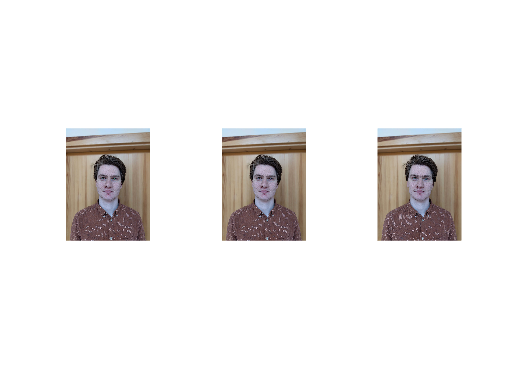

I_n = I;

I_n = I_n.*cast(maskedImage,"uint8");

I_p = I - I_n;

figure
title("Different shifts in color")
tiledlayout(1,3)

for shift = 1:3
    I_c = I_p;
    for i = 1:3
        I_c(:,:,mod(i,3)+1) = I_c(:,:,mod(i,3) + 1) + I_n(:,:,mod(i + shift,3)+1);
    end
    nexttile
    imshow(I_c)
end

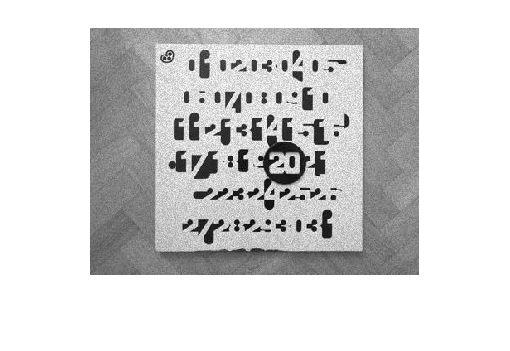

C = imread("img\calendar_speckle10.jpg");
C = im2double(C);
figure
imshow(C)



s = fspecial("sobel");
g = fspecial("gaussian");
tic
for i = 1:1000
    A = conv2(conv2(C,s),g);
end
toc

Elapsed time is 0.684177 seconds.


tic
for i = 1:1000
    B = conv2(C,conv2(s,g));
end
toc

Elapsed time is 0.237413 seconds.


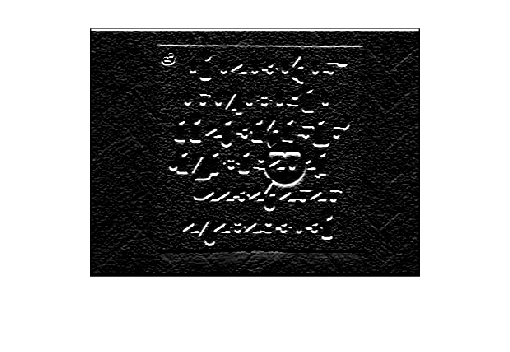

imshow(A)

imshow(B)

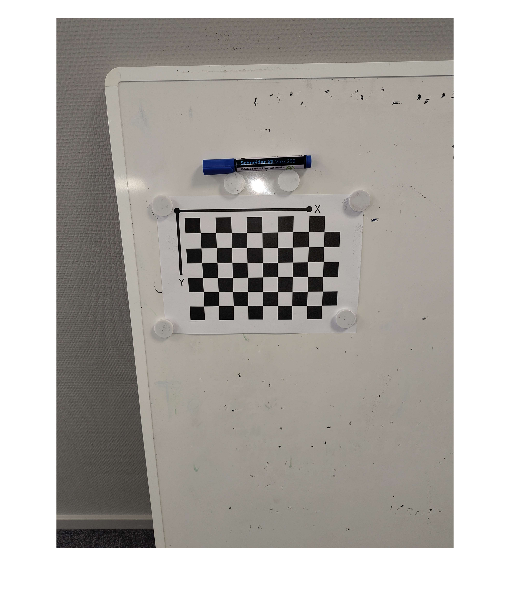

Pen1 = imread("./Pen1.jpg");
Pen2 = imread("./Pen2.jpg");
cameraParams = load("cameraParams.mat").cameraParams;
imshow(Pen1)

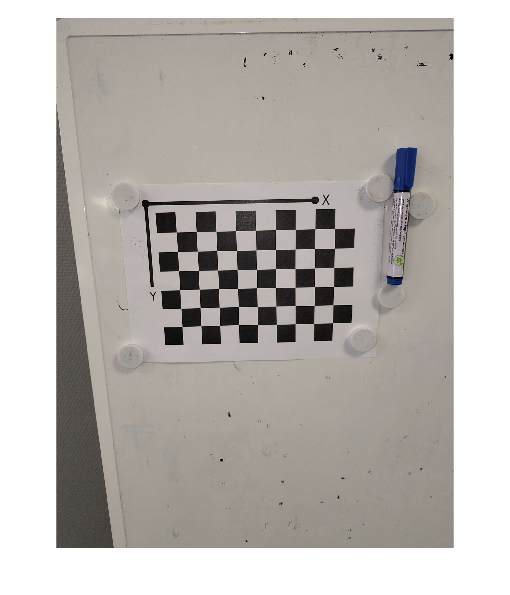

imshow(Pen2)

TruePenLength = 145;
TrueSquareSize = 22;

Pen1_pxlen = 828.97 %Measued in the image viewer app

Pen1_pxlen = 828.9700

Pen2_pxlen = 1031.43 %Measured in the image viewer app

Pen2_pxlen = 1.0314e+03

square_size1 = (1188.01)/10 %Measured in the image viewer app

square_size1 = 118.8010

square_size2 = (1536.19)/10 %Measured in the image viewer app

square_size2 = 153.6190


pixelSize1 = TrueSquareSize/square_size1 %Measurd by hand

pixelSize1 = 0.1852

pixelSize2 = TrueSquareSize/square_size2 %Measured by hand

pixelSize2 = 0.1432


distorted_pen1_len = Pen1_pxlen*pixelSize1

distorted_pen1_len = 153.5117

distorted_pen2_len = Pen2_pxlen*pixelSize2

distorted_pen2_len = 147.7126


f = cameraParams.Intrinsics.FocalLength(1); %Gained from the camera calibrator app

z1 = f*pixelSize1*TruePenLength/distorted_pen1_len %Function derived from pinhole approximation slide h'/h = f/z 

z1 = 495.8215

z2 = f*pixelSize2*TruePenLength/distorted_pen2_len %Function derived from pinhole approximation slide h'/h = f/z 

z2 = 398.4964

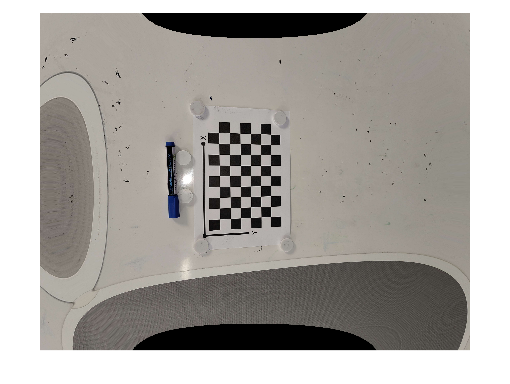

A=undistortImage(imrotate(Pen1,90),cameraParams,'OutputView','full');
imshow(A)

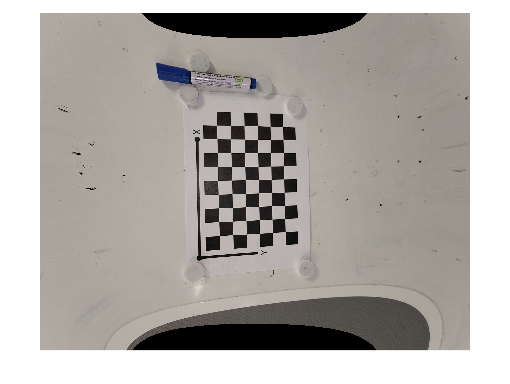

B=undistortImage(imrotate(Pen2,90),cameraParams,'OutputView','full');
imshow(B)


NewPen1_pxlen = 838.39 %Measured in the image viewer app

NewPen1_pxlen = 838.3900

NewPen2_pxlen = 1108.03 %Measured in the image viewer app

NewPen2_pxlen = 1.1080e+03


square_size3 = 1188.28/10 %Measured in the image viewer app

square_size3 = 118.8280

square_size4 = 1521.68/10 %Measured in the image viewer app

square_size4 = 152.1680


pixelSize3 = TrueSquareSize/square_size3

pixelSize3 = 0.1851

pixelSize4 = TrueSquareSize/square_size4

pixelSize4 = 0.1446


undistorted_pen1_len = TrueSquareSize*NewPen1_pxlen/square_size3

undistorted_pen1_len = 155.2208

undistorted_pen2_len = TrueSquareSize*NewPen2_pxlen/square_size4

undistorted_pen2_len = 160.1957



z3 = f*pixelSize3*TruePenLength/undistorted_pen1_len %Function derived from pinhole approximation slide h'/h = f/z 

z3 = 490.2506

z4 = f*pixelSize4*TruePenLength/undistorted_pen2_len %Function derived from pinhole approximation slide h'/h = f/z 

z4 = 370.9477

function NewArray = typecastarray(TheArray, NewType)
  curshape = num2cell(size(TheArray));
  NewArray = reshape( typecast(TheArray(:),NewType), [], curshape{2:end});
end